theta1=0;d1=0;a1=10;alpha1=0; %parameter link1
theta2=0;d2=0;a2=10;alpha2=0; %parameter link2
theta3=0;d3=0;a3=5;alpha3=0; %parameter link3
T01=DHmatrix(theta1,d1,a1,alpha1);
T12=DHmatrix(theta2,d2,a2,alpha2);
T23=DHmatrix(theta3,d3,a3,alpha3);
T02=T01*T12;
T03=T01*T12*T23

T03 =      1     0     0    25
     0     1     0     0
     0     0     1     0
     0     0     0     1


theta1 = -331.734+360;
theta2 = 123.120;
theta3 = 573.349-360;
T01=DHmatrix(theta1,d1,a1,alpha1);
T12=DHmatrix(theta2,d2,a2,alpha2);
T23=DHmatrix(theta3,d3,a3,alpha3);
endq = [theta1, theta2, theta3]

endq =    28.2660  123.1200  213.3490


T02=T01*T12;
T03=T01*T12*T23

T03 =     0.4020         0         0    6.0052
   -0.1355    0.4020   -1.4758    8.8473
         0         0    1.0000         0
         0         0         0    1.0000


P1=transpose(T01(1:2,4));
P2=transpose(T02(1:2,4));
P3=transpose(T03(1:2,4));
P0 =[0, 0, 0]

P0 =      0     0     0


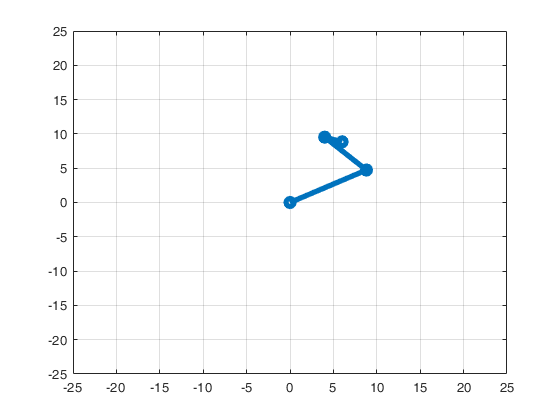

 
r = 
 
noname:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         10|          0|          0|
|  2|         q2|          0|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


Q1=[P0(1,1) P1(1,1) P2(1,1) P3(1,1)];
Q2=[P0(1,2) P1(1,2) P2(1,2) P3(1,2)];
plot(Q1,Q2,'-o','LineWidth',4);
axis([-25,25,-25,25]);

DH_(1) = Link([0 0 10 0]);
DH_(2) = Link([0 0 10 0]);
th_1 = (0:0.05:pi) ;
th_2 = (-pi:0.05:pi);
q_ = {th_1, th_1};
plotworkspace(DH_,q_)

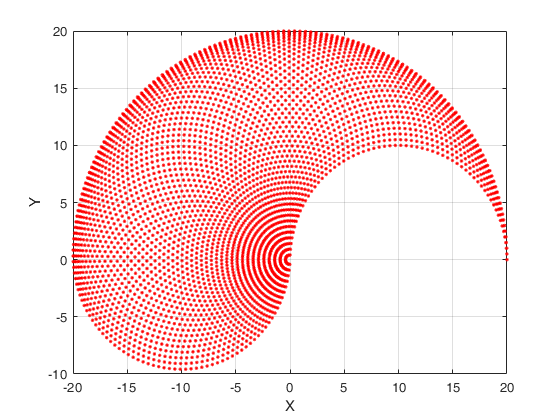

 
r = 
 
noname:: 3 axis, RRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         10|          0|          0|
|  2|         q2|          0|         10|          0|          0|
|  3|         q3|          0|          5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


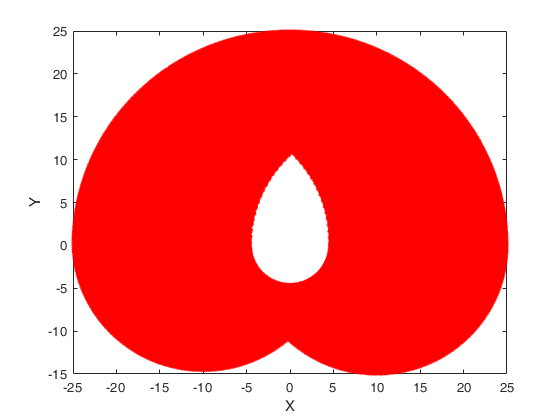


DH(1) = Link([0 0 10 0]);
DH(2) = Link([0 0 10 0]);
DH(3) = Link([0 0 5 0]);
th1 = (0:0.05:pi) ;
th2 = (-pi:0.05:pi);
th3 = (-pi/6:0.05:pi/6);
q = {th1, th2, th3};
plotworkspace(DH,q)

clc
clear
l(1) = Link([0, 0.478, 0, -pi/2])

 
l = 
Revolute(std): theta=q, d=0.478, a=0, alpha=-1.5708, offset=0


l(1).qlim = [-pi/2 pi/2]

 
l = 
Revolute(std): theta=q, d=0.478, a=0, alpha=-1.5708, offset=0


l(2) = Link([0, 0, 0.05, 0]);
l(2).qlim = [deg2rad(-130) deg2rad(147.5)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          


l(3) = Link([0, 0.05, 0.425, 0]);
l(3).qlim = [deg2rad(-145) deg2rad(145)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          


l(4) = Link([0, 0, 0, pi/2]);
l(4).qlim = [deg2rad(-270) deg2rad(270)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          
Revolute(std):  theta=q4   d=0           a=0           alpha=1.571       offset=0          


l(5) = Link([0, 0.425, 0, 0]);
l(5).qlim = [deg2rad(-115) deg2rad(140)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          
Revolute(std):  theta=q4   d=0           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q5   d=0.425       a=0           alpha=0           offset=0          


l(6) = Link([0, 0.100, 0, 0]);
l(6).qlim = [deg2rad(-270) deg2rad(270)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          
Revolute(std):  theta=q4   d=0           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q5   d=0.425       a=0           alpha=0           offset=0          
Revolute(std):  theta=q6   d=0.1         a=0           alpha=0           offset=0          


goal = SE3(0.43, 0.05, 0.9);
staubli = SerialLink(l, 'name', 'staubli_rtb');
staubli.links;
J= zeros(6,6);
U =staubli.tool;
staubli.mdh;
q =[0 0 0 0 0 0];
for j=6:-1:1
    U = l(j).A(q(j)) * U;
    UT=U.T;
    d = [   -UT(1,1)*UT(2,4)+UT(2,1)*UT(1,4)
        -UT(1,2)*UT(2,4)+UT(2,2)*UT(1,4)
        -UT(1,3)*UT(2,4)+UT(2,3)*UT(1,4)]
    delta = UT(3,1:3)' % nz oz az
    J(:,j) = [d; delta]
end

d =      0
     0
     0


delta =      0
     0
     1


J =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     1


d =      0
     0
     0


delta =      0
     0
     1


J =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     1     1


d =     0.5250
         0
         0


delta =          0
    1.0000
    0.0000


J =          0         0         0    0.5250         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0    1.0000         0         0
         0         0         0    0.0000    1.0000    1.0000


d =     0.5250
    0.0000
   -0.4250


delta =          0
    1.0000
    0.0000


J =          0         0    0.5250    0.5250         0         0
         0         0    0.0000         0         0         0
         0         0   -0.4250         0         0         0
         0         0         0         0         0         0
         0         0    1.0000    1.0000         0         0
         0         0    0.0000    0.0000    1.0000    1.0000


d =     0.5250
    0.0000
   -0.4750


delta =          0
    1.0000
    0.0000


J =          0    0.5250    0.5250    0.5250         0         0
         0    0.0000    0.0000         0         0         0
         0   -0.4750   -0.4250         0         0         0
         0         0         0         0         0         0
         0    1.0000    1.0000    1.0000         0         0
         0    0.0000    0.0000    0.0000    1.0000    1.0000


d =    -0.0500
    0.4750
         0


delta =      0
     0
     1


J =    -0.0500    0.5250    0.5250    0.5250         0         0
    0.4750    0.0000    0.0000         0         0         0
         0   -0.4750   -0.4250         0         0         0
         0         0         0         0         0         0
         0    1.0000    1.0000    1.0000         0         0
    1.0000    0.0000    0.0000    0.0000    1.0000    1.0000


J = J(4:6,:)

J =          0         0         0         0         0         0
         0    1.0000    1.0000    1.0000         0         0
    1.0000    0.0000    0.0000    0.0000    1.0000    1.0000


cIKTE = staubli.fkine([0 0 0 0 0 0])

 

cIKTE = 
         1         0         0     0.475
         0         1         0      0.05
         0         0         1     1.003
         0         0         0         1


e = tr2delta(cIKTE, goal)

e =    -0.0450
         0
   -0.1030
         0
         0
         0


% staubli.n = 6dof
% cIKTE = staubli.fkine([0 -pi/2 0 pi/2 0 0])
ik_sol = staubli.ikine(goal,'mask',[1 1 1 1 1 1])

ik_sol =     0.0000   -0.9316    1.2751   -0.3435   -0.0000   -0.0000



%staubli.plot(ik_sol, 'tilesize', 2)
cIKTE = staubli.fkine([0 0 0 0 0 0]);

T1 = SE3(0.475, 0.05, 1.003);
T2 = SE3(0.43, 0.05, 0.9);
q = staubli.jtraj(T1,T2,10)

q =          0         0         0         0         0         0
    0.0000   -0.0107    0.0147   -0.0040   -0.0000   -0.0000
    0.0000   -0.0712    0.0974   -0.0262   -0.0000   -0.0000
    0.0000   -0.1955    0.2676   -0.0721   -0.0000   -0.0000
    0.0000   -0.3696    0.5058   -0.1363   -0.0000   -0.0000
    0.0000   -0.5621    0.7693   -0.2072   -0.0000   -0.0000
    0.0000   -0.7361    1.0075   -0.2714   -0.0000   -0.0000
    0.0000   -0.8604    1.1777   -0.3172   -0.0000   -0.0000
    0.0000   -0.9209    1.2604   -0.3395   -0.0000   -0.0000
    0.0000   -0.9316    1.2751   -0.3435   -0.0000   -0.0000


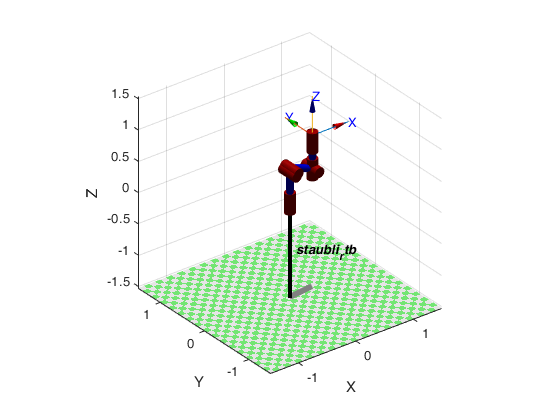

figure(1)
staubli.plot(q)

%staubli.plot3d(q, 'view', ae, 'movie', 'move2ball.gif');
%staubli.plot([0, 0, 0, 0, 0, 0]);


syms theta alpha a d l1 real
test(1) = Link([theta, d, a, alpha])

 
test = 
Revolute(std): theta=q, d=d, a=a, alpha=alpha, offset=0


one_link = SerialLink(test, 'name', 'one_link');
clkTE = one_link.fkine([theta])

$$\left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

clc
clear
theta1=0;d1=0.478;a1=0;    alpha1=-90; %parameter link1
theta2=0;d2=0;    a2=0.05; alpha2=0; %parameter link2
theta3=0;d3=0.05; a3=0.425;alpha3=0; %parameter link3

theta4=0;d4=0;    a4=0;    alpha4=90;
theta5=0;d5=0.425;a5=0;    alpha5=0;
theta6=0;d6=0.100;a6=0;    alpha6=0;

T01=DHmatrix(theta1,d1,a1,alpha1)

'DHmatrix' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\UNIST\Desktop\manipulator_study\m_files\3link_test

Change the MATLAB current folder or add its folder to the MATLAB path.

T12=DHmatrix(theta2,d2,a2,alpha2);
T23=DHmatrix(theta3,d3,a3,alpha3);
T34=DHmatrix(theta4,d4,a4,alpha4); 
T45=DHmatrix(theta5,d5,a5,alpha5);
T56=DHmatrix(theta6,d6,a6,alpha6); 
T02=T01*T12
T03=T01*T12*T23
T04=T03*T34
T05=T04*T45
T06=T05*T56

clc
clear
theta1=0;  d1=478;   a1=0;  alpha1=-90; %parameter link1
theta2=0;  d2=0;   a2=50;  alpha2=0; %parameter link2
theta3=0;  d3=50;  a3=425;  alpha3=0; %parameter link3
theta4=0;  d4=0;   a4=0;  alpha4=90; %parameter link4
theta5=0;  d5=425; a5=0;  alpha5=0; %parameter link5
theta6=0;  d6=100; a6=0;  alpha6=0; %parameter link6

    T01=[cosd(theta1) -cosd(alpha1)*sind(theta1) sind(alpha1)*sind(theta1) a1*cosd(theta1);
        sind(theta1) cosd(alpha1)*cosd(theta1)  -sind(alpha1)*cosd(theta1) a1*sind(theta1);
        0,sind(alpha1),cosd(alpha1),d1;
        0,0,0,1];
    T12=[cosd(theta2) -cosd(alpha2)*sind(theta2) sind(alpha2)*sind(theta2) a2*cosd(theta2);
        sind(theta2) cosd(alpha2)*cosd(theta2)  -sind(alpha2)*cosd(theta2) a2*sind(theta2);
        0,sind(alpha2),cosd(alpha2),d2;
        0,0,0,1];
    T23=[cosd(theta3) -cosd(alpha3)*sind(theta3) sind(alpha3)*sind(theta3) a3*cosd(theta3);
        sind(theta3) cosd(alpha3)*cosd(theta3)  -sind(alpha3)*cosd(theta3) a3*sind(theta3);
        0,sind(alpha3),cosd(alpha3),d3;
        0,0,0,1];
    T34=[cosd(theta4) -cosd(alpha4)*sind(theta4) sind(alpha4)*sind(theta4) a4*cosd(theta4);
         sind(theta4) cosd(alpha4)*cosd(theta4)  -sind(alpha4)*cosd(theta4) a4*sind(theta4);
         0,sind(alpha4),cosd(alpha4),d4;
         0,0,0,1];
    T45=[cosd(theta5) -cosd(alpha5)*sind(theta5) sind(alpha5)*sind(theta5) a5*cosd(theta5);
         sind(theta5) cosd(alpha5)*cosd(theta5)  -sind(alpha5)*cosd(theta5) a5*sind(theta5);
         0,sind(alpha5),cosd(alpha5),d5;
         0,0,0,1];
    T56=[cosd(theta6) -cosd(alpha6)*sind(theta6) sind(alpha6)*sind(theta6) a6*cosd(theta6);
         sind(theta6) cosd(alpha6)*cosd(theta6)  -sind(alpha6)*cosd(theta6) a6*sind(theta6);
         0,sind(alpha6),cosd(alpha6),d6;
         0,0,0,1];

T06=T01*T12*T23*T34*T45*T56

T06 =            1           0           0         475
           0           1           0          50
           0           0           1        1003
           0           0           0           1


clc
clear
l(1) = Link([0, 0.478, 0, -pi/2])

 
l = 
Revolute(std): theta=q, d=0.478, a=0, alpha=-1.5708, offset=0


l(1).qlim = [-pi/2 pi/2]

 
l = 
Revolute(std): theta=q, d=0.478, a=0, alpha=-1.5708, offset=0


l(2) = Link([0, 0, 0.05, 0]);
l(2).qlim = [deg2rad(-130) deg2rad(147.5)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          


l(3) = Link([0, 0.05, 0.425, 0]);
l(3).qlim = [deg2rad(-145) deg2rad(145)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          


l(4) = Link([0, 0, 0, pi/2]);
l(4).qlim = [deg2rad(-270) deg2rad(270)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          
Revolute(std):  theta=q4   d=0           a=0           alpha=1.571       offset=0          


l(5) = Link([0, 0.425, 0, 0]);
l(5).qlim = [deg2rad(-115) deg2rad(140)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          
Revolute(std):  theta=q4   d=0           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q5   d=0.425       a=0           alpha=0           offset=0          


l(6) = Link([0, 0.100, 0, 0]);
l(6).qlim = [deg2rad(-270) deg2rad(270)]

 
l = 
Revolute(std):  theta=q1   d=0.478       a=0           alpha=-1.571      offset=0          
Revolute(std):  theta=q2   d=0           a=0.05        alpha=0           offset=0          
Revolute(std):  theta=q3   d=0.05        a=0.425       alpha=0           offset=0          
Revolute(std):  theta=q4   d=0           a=0           alpha=1.571       offset=0          
Revolute(std):  theta=q5   d=0.425       a=0           alpha=0           offset=0          
Revolute(std):  theta=q6   d=0.1         a=0           alpha=0           offset=0          


deg2rad(0)

ans = 0

q =[deg2rad(0) deg2rad(0) deg2rad(-90) deg2rad(90) deg2rad(0) deg2rad(0)];
staubli = SerialLink(l, 'name', 'staubli_rtb');
staubli.fkine(q)

 

ans = 
         1         0         0      0.05
         0         1         0      0.05
         0         0         1     1.428
         0         0         0         1


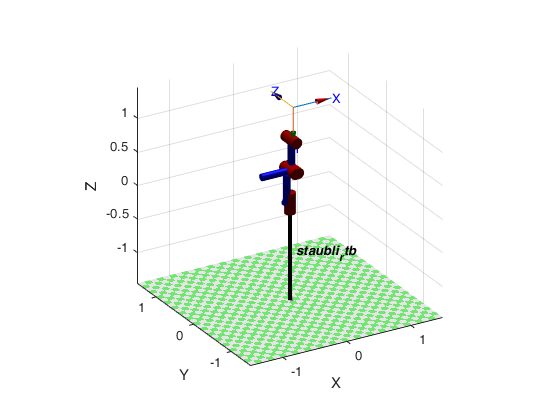

Index exceeds the number of array elements (5).

Error in SerialLink/animate (line 105)
                        if h.link(L) ~= 0

Error in SerialLink/plot (line 299)
    robot.animate(qq);

staubli.plot(q)

% q0 =[deg2rad(0) deg2rad(0) deg2rad(90) deg2rad(0) deg2rad(0) deg2rad(0)];
% staubli2 = SerialLink(l, 'name', 'staubli_rt2b');
% staubli2.fkine(q0)
% staubli2.plot(q0)

clc
clear
l(1) = Link([0, 0.478, 0.05, -pi/2])

 
l = 
Revolute(std): theta=q, d=0.478, a=0.05, alpha=-1.5708, offset=0


l(2) = Link([0, 0.0, 0.05, 0]);
l(3) = Link([0, 0.05, 0.425, 0]);
l(4) = Link([0, 0, 0, pi/2]);
l(5) = Link([0, 0.425, 0, 0]);
l(6) = Link([0, 0.100, 0, 0]);
deg2rad(0)

ans = 0

q =[deg2rad(0) deg2rad(0) deg2rad(-90) deg2rad(90) deg2rad(0) deg2rad(0)];
staubli = SerialLink(l, 'name', 'staubli_rtb');
staubli.fkine(q)

 

ans = 
         1         0         0       0.1
         0         1         0      0.05
         0         0         1     1.428
         0         0         0         1


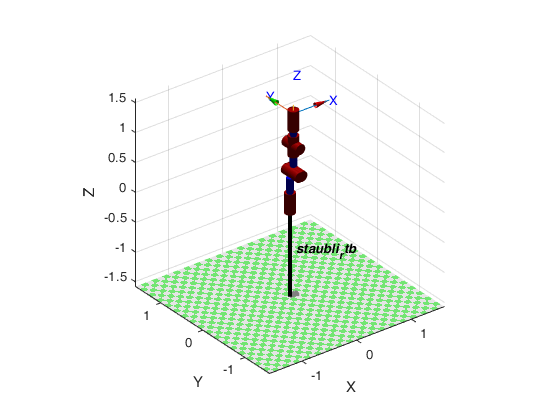

staubli.plot(q)

% q0 =[deg2rad(0) deg2rad(0) deg2rad(90) deg2rad(0) deg2rad(0) deg2rad(0)];
% staubli2 = SerialLink(l, 'name', 'staubli_rt2b');
% staubli2.fkine(q0)
% staubli2.plot(q0)

clc
clear
% dh = [theta, d(z), a(x), alpha, sigma, offset]
l(1) = Link([0, 0.0, 0.05, -pi/2, 0.0, 0.0]);
l(2) = Link([0, 0.0, 0.425, 0.0, 0.0, -pi/2]); 
l(3) = Link([0, 0.05, 0.425,  0.0, 0.0, 0]);
l(4) = Link([0, 0.0, 0.0,  pi/2, 0.0, pi/2]);

l(5) = Link([0, 0.1, 0.0,  -pi/2, 0.0, 0.0]);
l(6) = Link([0, 0.0, 0.0,  pi/2, 0.0, 0.0]);
staubli = SerialLink(l, 'name', 'staubli_rtb');
q0 =[0 0 0 0 0 0]

q0 =      0     0     0     0     0     0


q =[-0.023 28.14 49.22 167.6 45.45 8.244]; %0 0
staubli.fkine(q)

 

ans = 
    0.0301   -0.9885    0.1480    0.4925
   -0.3790    0.1257    0.9168   0.03868
   -0.9249   -0.0837   -0.3709   -0.4835
         0         0         0         1


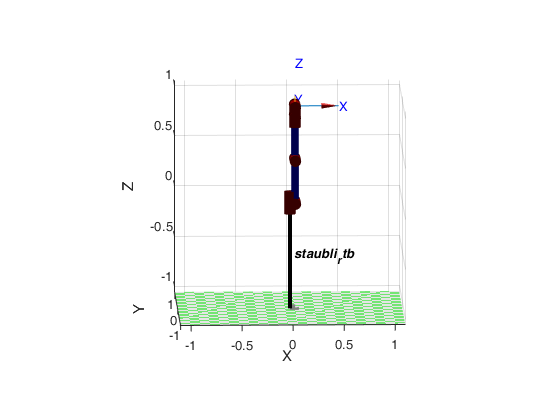

staubli.plot(q0)


theta1=0;  d1=0;   a1=50;  alpha1=-90; %parameter link1
theta2=-90;  d2=0;   a2=425;  alpha2=0; %parameter link2
theta3=0;  d3=50;  a3=425;  alpha3=0; %parameter link3
theta4=0+90;  d4=0;   a4=0;  alpha4=90; %parameter link4
theta5=0;  d5=100; a5=0;  alpha5=-90; %parameter link5
theta6=0;  d6=0; a6=0;  alpha6=90; %parameter link6
    T01=[cosd(theta1) -cosd(alpha1)*sind(theta1) sind(alpha1)*sind(theta1) a1*cosd(theta1);
        sind(theta1) cosd(alpha1)*cosd(theta1)  -sind(alpha1)*cosd(theta1) a1*sind(theta1);
        0,sind(alpha1),cosd(alpha1),d1;
        0,0,0,1];
    T12=[cosd(theta2) -cosd(alpha2)*sind(theta2) sind(alpha2)*sind(theta2) a2*cosd(theta2);
        sind(theta2) cosd(alpha2)*cosd(theta2)  -sind(alpha2)*cosd(theta2) a2*sind(theta2);
        0,sind(alpha2),cosd(alpha2),d2;
        0,0,0,1];
    T23=[cosd(theta3) -cosd(alpha3)*sind(theta3) sind(alpha3)*sind(theta3) a3*cosd(theta3);
        sind(theta3) cosd(alpha3)*cosd(theta3)  -sind(alpha3)*cosd(theta3) a3*sind(theta3);
        0,sind(alpha3),cosd(alpha3),d3;
        0,0,0,1];
    T34=[cosd(theta4) -cosd(alpha4)*sind(theta4) sind(alpha4)*sind(theta4) a4*cosd(theta4);
         sind(theta4) cosd(alpha4)*cosd(theta4)  -sind(alpha4)*cosd(theta4) a4*sind(theta4);
         0,sind(alpha4),cosd(alpha4),d4;
         0,0,0,1];
    T45=[cosd(theta5) -cosd(alpha5)*sind(theta5) sind(alpha5)*sind(theta5) a5*cosd(theta5);
         sind(theta5) cosd(alpha5)*cosd(theta5)  -sind(alpha5)*cosd(theta5) a5*sind(theta5);
         0,sind(alpha5),cosd(alpha5),d5;
         0,0,0,1];
    T56=[cosd(theta6) -cosd(alpha6)*sind(theta6) sind(alpha6)*sind(theta6) a6*cosd(theta6);
         sind(theta6) cosd(alpha6)*cosd(theta6)  -sind(alpha6)*cosd(theta6) a6*sind(theta6);
         0,sind(alpha6),cosd(alpha6),d6;
         0,0,0,1];
    T01;
    T02 = T01*T12;
    T03=T01*T12*T23;
    T04=T01*T12*T23*T34;
    T05=T01*T12*T23*T34*T45;
    T06=T01*T12*T23*T34*T45*T56

T06 =      1     0     0   900
     0     1     0    50
     0     0     1   100
     0     0     0     1
